% This example demonstrate how a Maneuver Automaton can be constructed and
% applied to solve an online control task for an autonomous truck.


% Generate Motion Primitives ----------------------------------------------

% load postprocessing function 
Post = @postprocessing_truck;

% load system parameter
Params = param_truck();
Params.R0 = Params.R0 + (-center(Params.R0)) + [0; 0; 0; 16.79; 0; 0];

% define algorithm options
Opts1 = [];

Opts1.N = 30;                           % number of time steps
Opts1.Ninter = 4;                       % number of intermediate steps
Opts1.reachSteps = 20;                  % number of reachability steps
Opts1.Q = diag([1,1,1,1,10,10]);        % state weighting matrix
Opts1.R = 1e-6*eye(2);                  % input weighting matrix

Opts2 = [];

Opts2.N = 10;                           % number of time steps
Opts2.Ninter = 5;                       % number of intermediate steps
Opts2.reachSteps = 20;                  % number of reachability steps
Opts2.Q = diag([2,14,12,1,10,40]);      % state weighting matrix
Opts2.R = 1e-6*eye(2);                  % input weighting matrix

% define control inputs and initial states for motion primitives
list_xf = {[0;0;0;16.79;50.37;-3.68], ...
                        [0;0;0;16.79;50.37;3.68],[0;0;0;16.79;16.79;0]};
list_tFinal = {3, 3, 1};
list_Opts = {Opts1, Opts1, Opts2};

% loop over all motion primitives
primitives = {};
counter = 1;

for i = 1:length(list_xf)

    disp([newline,'Motion primitive ',num2str(counter), ...
         ' --------------',newline]);

    % update parameter and settings
    Params.xf = list_xf{i};
    Params.tFinal = list_tFinal{i};
    Opts = list_Opts{i};

    % compute controller for the current motion primitive
    [obj,res] = generatorSpaceControl('truck',Params,Opts,Post);

    primitives{counter} = obj;
    counter = counter + 1;
end


Motion primitive 1 --------------



Time step: 1
Time step: 2
Time step: 3
Time step: 4
Time step: 5
Time step: 6
Time step: 7
Time step: 8
Time step: 9
Time step: 10
Time step: 11
Time step: 12
Time step: 13
Time step: 14
Time step: 15
Time step: 16
Time step: 17
Time step: 18
Time step: 19
Time step: 20
Time step: 21
Time step: 22
Time step: 23
Time step: 24
Time step: 25
Time step: 26
Time step: 27
Time step: 28
Time step: 29
Time step: 30



Motion primitive 2 --------------



Time step: 1
Time step: 2
Time step: 3
Time step: 4
Time step: 5
Time step: 6
Time step: 7
Time step: 8
Time step: 9
Time step: 10
Time step: 11
Time step: 12
Time step: 13
Time step: 14
Time step: 15
Time step: 16
Time step: 17
Time step: 18
Time step: 19
Time step: 20
Time step: 21
Time step: 22
Time step: 23
Time step: 24
Time step: 25
Time step: 26
Time step: 27
Time step: 28
Time step: 29
Time step: 30



Motion primitive 3 --------------



Time step: 1
Time step: 2
Time step: 3
Time step: 4
Time step: 5
Time step: 6
Time step: 7
Time step: 8
Time step: 9
Time step: 10




% Construct Maneuver Automaton --------------------------------------------

% assemble input arguments
shiftFun = @shiftInitSet_truck;
shiftOccFun = @shiftOccupancySet_truck;

% construct maneuver automaton
MA = maneuverAutomaton(primitives,shiftFun,shiftOccFun);


% Online Control ----------------------------------------------------------

% load a CommonRoad traffic scenario
scenario = 'USA_US101-6_2_T-1';
[statObs,dynObs,x0,goalSet,lanelets] = commonroad2cora(scenario);

--------------
Successfully converted
USA_US101-6_2_T-1.xml with
5 lanelets,
0 static obstacles,
14 dynamic obstacles,
1 planning problem with
1 goal regions in
2.59 seconds.
--------------


x0 = [0; x0.orientation; 0; x0.velocity; x0.x-0.1; x0.y];
goalSet{1}.time = interval(3,4);

% plan a verified trajectory with the maneuver automaton
clock = tic;
ind = motionPlanner(MA,x0,goalSet{1},[],dynObs,'depth-first');
tComp = toc(clock);

disp([newline,'Computation time (motion planning): ',num2str(tComp),'s']);


Computation time (motion planning): 21.5335s


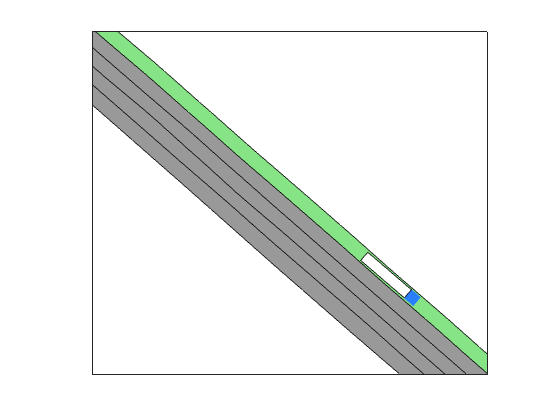



% Visualization -----------------------------------------------------------

% show the planned trajectory with an animation
resSim = simulateRandom(MA,ind,x0,1);
animate(resSim,'truck',[],dynObs,goalSet{1}.set,[],lanelets);

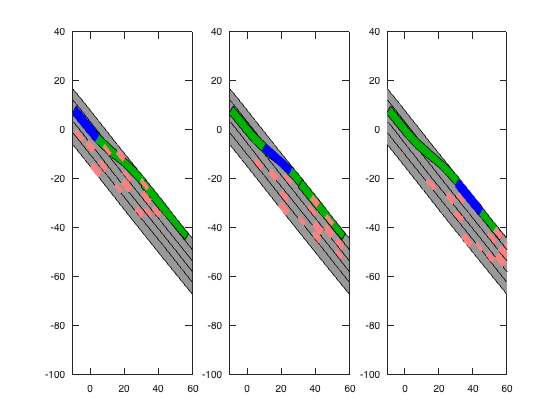


% visualize the planned trajectory for different times
figure
times = {0,1.5,3};

for i = 1:length(times)
   subplot(1,length(times),i); hold on; box on;
   for j = 1:length(lanelets)
        plot(lanelets{j},[1,2],'FaceColor',[.6 .6 .6],'EdgeColor','k');
   end
   plotPlannedTrajectory(MA,ind,x0,[],[0 0.7 0],'EdgeColor','k');
   plotPlannedTrajectory(MA,ind,x0,interval(times{i}),'b');
   plotObstacles([],dynObs,interval(times{i}-0.05,times{i}+0.05));
   xlim([-10,60]); ylim([-100,40]);
end